originalImg = imread("original.jpg")

originalImg = 359×479 uint8 matrix
   120   121   121   122   122   123   123   123   123   123   123   122   122   121   121   121   120   120   120   120   120   120   120   120   119   119   120   121   121   122   123   123   124   124   124   124   124   124   124   124   122   122   122   123   123   124   124   124   125   125
   122   122   123   123   124   124   124   125   123   123   123   122   122   121   121   121   120   120   120   120   120   120   120   120   119   119   120   121   121   122   123   123   124   124   124   124   124   124   124   124   122   122   122   123   123   124   124   124   125   125
   124   124   125   125   125   125   126   126   123   123   123   122   122   121   121   121   120   120   120   120   120   120   120   120   119   119   120   121   121   122   123   123   124   124   124   124   124   124   124   124   122   122   122   123   123   124   124   124   125   125
   125   125   125   125   125   125   126   126   123   123  

doubleOriginalImg = im2double(originalImg(:,:,1))

doubleOriginalImg =     0.4706    0.4745    0.4745    0.4784    0.4784    0.4824    0.4824    0.4824    0.4824    0.4824    0.4824    0.4784    0.4784    0.4745    0.4745    0.4745    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4667    0.4667    0.4706    0.4745    0.4745    0.4784    0.4824    0.4824    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4784    0.4784    0.4784    0.4824    0.4824    0.4863    0.4863    0.4863    0.4902    0.4902
    0.4784    0.4784    0.4824    0.4824    0.4863    0.4863    0.4863    0.4902    0.4824    0.4824    0.4824    0.4784    0.4784    0.4745    0.4745    0.4745    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4667    0.4667    0.4706    0.4745    0.4745    0.4784    0.4824    0.4824    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4784    0.4784    0.4784    0.4824    0.4824    0.4863    0.4863    0.486

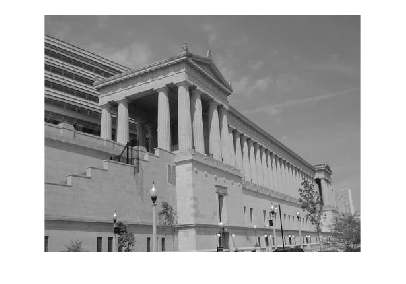

imshow(doubleOriginalImg)

LPF = ones(3,3)/9

LPF =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


filteredOriginalImg = imfilter(doubleOriginalImg, LPF, 'replicate')

filteredOriginalImg =     0.4741    0.4754    0.4776    0.4793    0.4815    0.4828    0.4841    0.4837    0.4832    0.4824    0.4810    0.4797    0.4771    0.4758    0.4745    0.4732    0.4719    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4693    0.4680    0.4680    0.4706    0.4732    0.4758    0.4784    0.4810    0.4837    0.4850    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4837    0.4810    0.4784    0.4797    0.4810    0.4837    0.4850    0.4863    0.4876    0.4889    0.4902
    0.4789    0.4802    0.4819    0.4837    0.4850    0.4863    0.4876    0.4863    0.4845    0.4824    0.4810    0.4797    0.4771    0.4758    0.4745    0.4732    0.4719    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4693    0.4680    0.4680    0.4706    0.4732    0.4758    0.4784    0.4810    0.4837    0.4850    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4837    0.4810    0.4784    0.4797    0.4810    0.4837    0.4850    0.4863    0.4

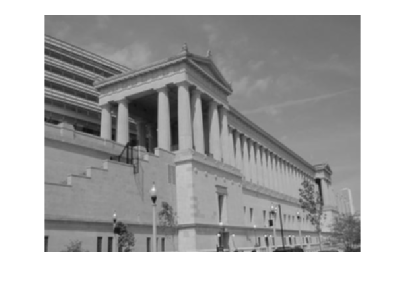

imshow(filteredOriginalImg)

downsampledOriginalImg = filteredOriginalImg(1:2:end, 1:2:end, 1)

downsampledOriginalImg =     0.4741    0.4776    0.4815    0.4841    0.4832    0.4810    0.4771    0.4745    0.4719    0.4706    0.4706    0.4706    0.4680    0.4706    0.4758    0.4810    0.4850    0.4863    0.4863    0.4863    0.4810    0.4797    0.4837    0.4863    0.4889    0.4902    0.4902    0.4902    0.4902    0.4902    0.4902    0.4902    0.4876    0.4863    0.4863    0.4863    0.4898    0.4919    0.4963    0.5046    0.5146    0.5237    0.5320    0.5338    0.5338    0.5386    0.5368    0.5277    0.5159    0.4985
    0.4850    0.4867    0.4885    0.4911    0.4858    0.4810    0.4771    0.4745    0.4728    0.4719    0.4719    0.4719    0.4693    0.4710    0.4758    0.4802    0.4837    0.4850    0.4850    0.4850    0.4806    0.4797    0.4837    0.4863    0.4880    0.4889    0.4889    0.4889    0.4889    0.4889    0.4889    0.4889    0.4871    0.4863    0.4863    0.4863    0.4858    0.4858    0.4906    0.4993    0.5098    0.5172    0.5203    0.5176    0.5224    0.5298    0.5325    

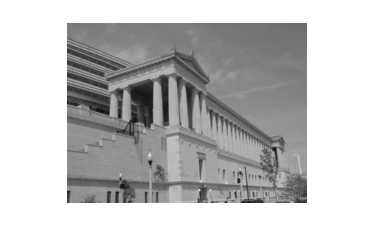

imshow(downsampledOriginalImg)

upSampling = zeros(359, 479)

upSampling =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

upSampling(1:2:end, 1:2:end) = downsampledOriginalImg

upSampling =     0.4741         0    0.4776         0    0.4815         0    0.4841         0    0.4832         0    0.4810         0    0.4771         0    0.4745         0    0.4719         0    0.4706         0    0.4706         0    0.4706         0    0.4680         0    0.4706         0    0.4758         0    0.4810         0    0.4850         0    0.4863         0    0.4863         0    0.4863         0    0.4810         0    0.4797         0    0.4837         0    0.4863         0    0.4889         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

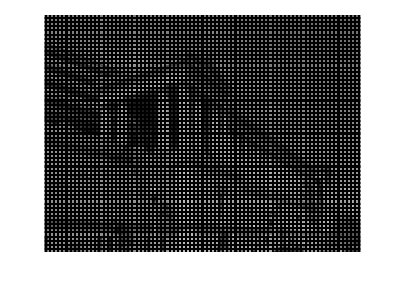

imshow(upSampling)

upFilter = [0.25, 0.5,0.25;
       0.5, 1, 0.5;
       0.25, 0.5, 0.25]

upFilter =     0.2500    0.5000    0.2500
    0.5000    1.0000    0.5000
    0.2500    0.5000    0.2500


upFilteredOriginalImg = imfilter(upSampling, upFilter)

upFilteredOriginalImg =     0.4741    0.4758    0.4776    0.4795    0.4815    0.4828    0.4841    0.4837    0.4832    0.4821    0.4810    0.4791    0.4771    0.4758    0.4745    0.4732    0.4719    0.4712    0.4706    0.4706    0.4706    0.4706    0.4706    0.4693    0.4680    0.4693    0.4706    0.4732    0.4758    0.4784    0.4810    0.4830    0.4850    0.4856    0.4863    0.4863    0.4863    0.4863    0.4863    0.4837    0.4810    0.4804    0.4797    0.4817    0.4837    0.4850    0.4863    0.4876    0.4889    0.4895
    0.4795    0.4808    0.4821    0.4836    0.4850    0.4863    0.4876    0.4861    0.4845    0.4828    0.4810    0.4791    0.4771    0.4758    0.4745    0.4734    0.4723    0.4718    0.4712    0.4712    0.4712    0.4712    0.4712    0.4699    0.4686    0.4697    0.4708    0.4733    0.4758    0.4782    0.4806    0.4825    0.4843    0.4850    0.4856    0.4856    0.4856    0.4856    0.4856    0.4832    0.4808    0.4803    0.4797    0.4817    0.4837    0.4850    0.4863    0

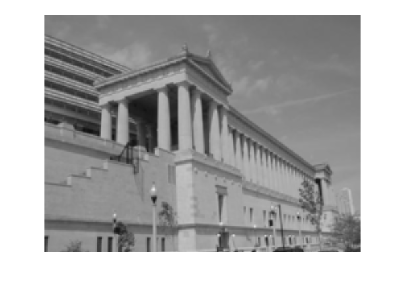

imshow(upFilteredOriginalImg)

originalImgPSNR = psnr(doubleOriginalImg, upFilteredOriginalImg)

originalImgPSNR = 28.1753